% Heeger and Simoncelli 1998


## load parameters

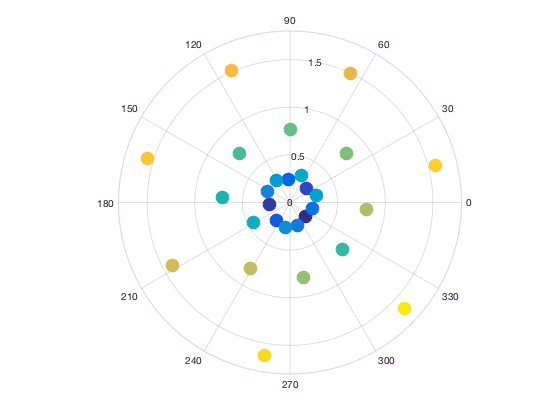

% load parameters
pars = shPars;
v1pref = pars.v1PopulationDirections;
nv1neurons = length(v1pref);

figure (1), clf
colors = parula(29);
for k = 1 : 28
polarplot(v1pref(k, 1), v1pref(k, 2), 'o', 'markerfacecolor', colors(k, :), 'markeredgecolor', colors(k, :)), hold on
end

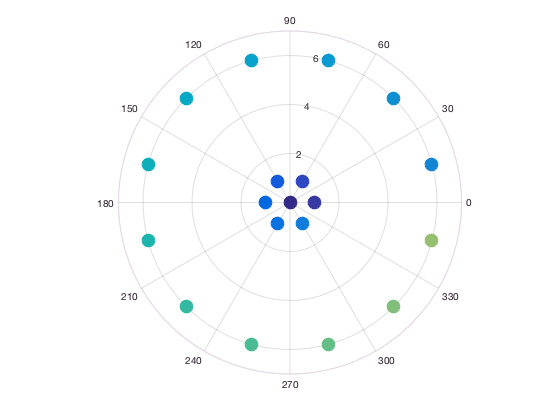

% mt neurons:
mtpref = pars.mtPopulationVelocities;% preferred direction , preferred speed
figure (2), clf
for k = 1 : 19
polarplot(mtpref(k, 1), mtpref(k, 2), 'o', 'markerfacecolor', colors(k, :), 'markeredgecolor', colors(k, :)), hold on
end

## characterize v1 spatial and temporal filters

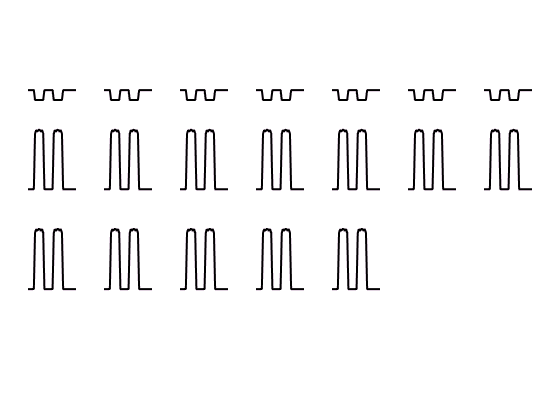

% mk stimulus (for characterizing v1 temporal filter)
stim = zeros(39, 39, 50); stim(:, :, 15:30) = 1;

%stim= ones(20, 20, 30);

[pop, ind] = shModel(stim, pars, 'MTpattern');
poprs = reshape(pop, [ind(2, 2), ind(2, 3), ind(2, 4), size(pop, 2)]);
figure (3), clf
for k = 1 : size(pop, 2)
    subplot_tight(4, 7, k, 0.05)
    plot(squeeze(poprs(3, 3, :, k)), 'k-'), axis tight, ylim([0, 0.8]), axis off
end

## testing stimulus

% stimuli: mkBar, mkDots, mkFract, mkGlass, mkPlaid, mkSin, mkWedge, mkWin
stimSz = [40, 40, 50];
bardir = [0, pi/2, pi, 3*pi/2];
barSpd = [0.1, 0.5, 1, 3];

for k2 = 1 : length(barSpd)
    for k1 = 1 : length(bardir)
        barstim{k1, k2} = mkBar(stimSz, bardir(k1), barSpd(k2)); % dir by spd
        % compute v1 simple response
        [pop1, ind1] = shModel(barstim{k1, k2}, pars, 'V1simple');
        [pop2, ind2] = shModel(barstim{k1, k2}, pars, 'V1complex');
        [pop3, ind3] = shModel(barstim{k1, k2}, pars, 'MTpattern');
        pop1rs{k1, k2} = reshape(pop1, [ind1(2, 2), ind1(2, 3), ind1(2, 4), size(pop1, 2)]);
        pop2rs{k1, k2} = reshape(pop2, [ind2(2, 2), ind2(2, 3), ind2(2, 4), size(pop2, 2)]);
        pop3rs{k1, k2} = reshape(pop3, [ind3(2, 2), ind3(2, 3), ind3(2, 4), size(pop3, 2)]);
    end
end

## visualize

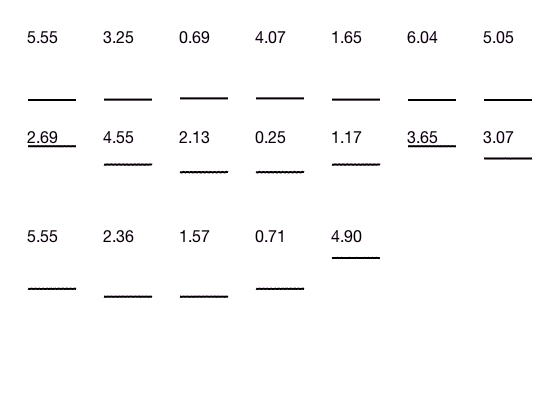


figure(3), clf
for k = 1  :size(pop3rs{1}, 4)
    subplot_tight(4, 7, k, 0.05)
    plot(squeeze(pop3rs{2,4}(2, 2, :, k)), 'k-'), axis tight, ylim([0, 1.5]), axis off
    text(0.5, 1.2,sprintf('%0.2f',pars.v1PopulationDirections(k, 1)))
end